# Epidemiological Model for COVID19 Pandemic in Colombia

Universidad Nacional de Colombia, July 2020

Authors:

- Juan Diego Ocampo M.

- Carlos Eduardo Aguilar B.

- Sebastián Ruiz T.

- María Camila Muñoz.

## Reset Simulation

clc
clearvars
close all
warning('off')

## Data Processing

Explain code here....

### Importing Data

data = importCSV('Colombia_COVID19.csv')

data = 118×7 table
    NUEVOS_CASOS    TOTAL_CASOS    TOTAL_MUERTES    TOTAL_RECUPERADOS    FECHA_ACTUALIZACION    NUEVOS_MUERTOS    NUEVO_RECUPERADOS
    ____________    ___________    _____________    _________________    ___________________    ______________    _________________

          1               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          2               3              0                  0                    N

dailyInfections = data.NUEVOS_CASOS;                                    % Daily Infections
dailyDeaths = data.NUEVOS_MUERTOS;                                      % Daily Fatalities
dailyRecoveries = data.NUEVO_RECUPERADOS;                               % Daily Recoveries
totalInfections = data.TOTAL_CASOS;                                     % Total Infections
totalDeaths = data.TOTAL_MUERTES;                                       % Total Fatalities
totalRecoveries = data.TOTAL_RECUPERADOS;                               % Total Recoveries
possibleDeaths = totalInfections - totalRecoveries;                     % Infected Remnants
timeElapsed = 1 : length(data.FECHA_ACTUALIZACION);                     % Elapsed Time since Patient Zero (in Days)

### Data Visualisation

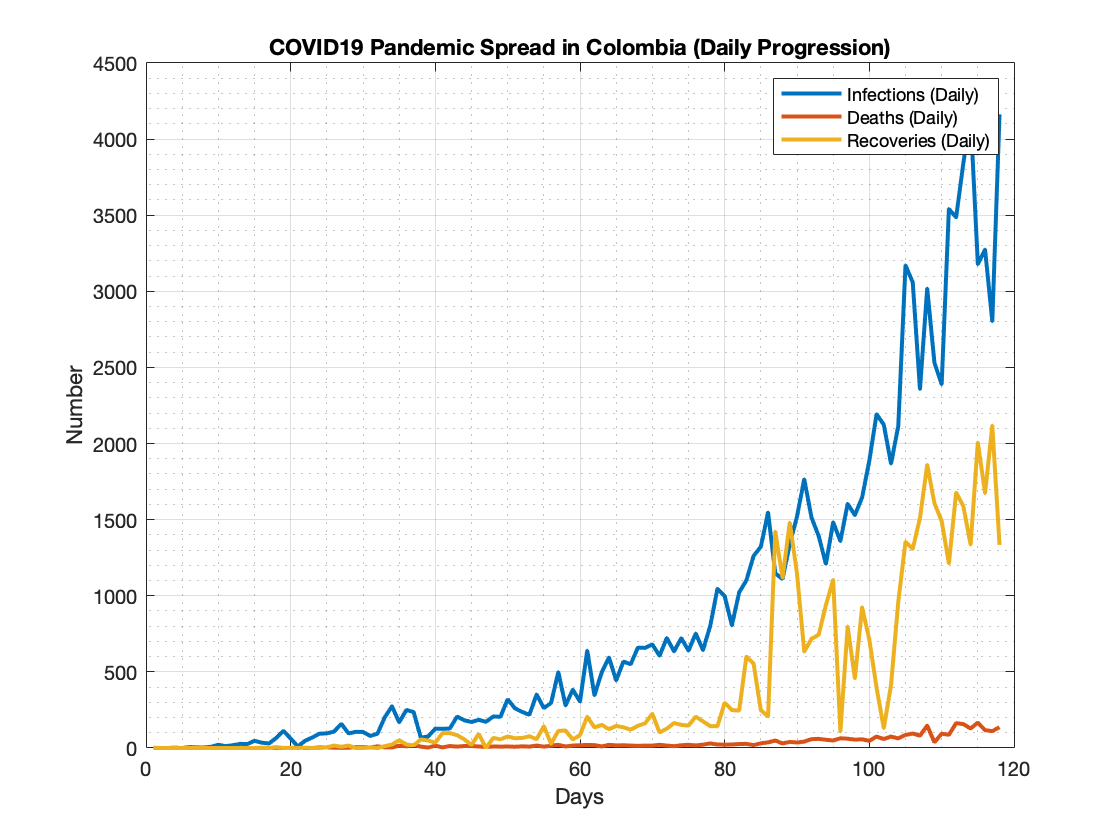

plot(timeElapsed,dailyInfections,timeElapsed,dailyDeaths,timeElapsed, dailyRecoveries, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Daily Progression)')
legend('Infections (Daily)','Deaths (Daily)','Recoveries (Daily)')
grid on, grid minor

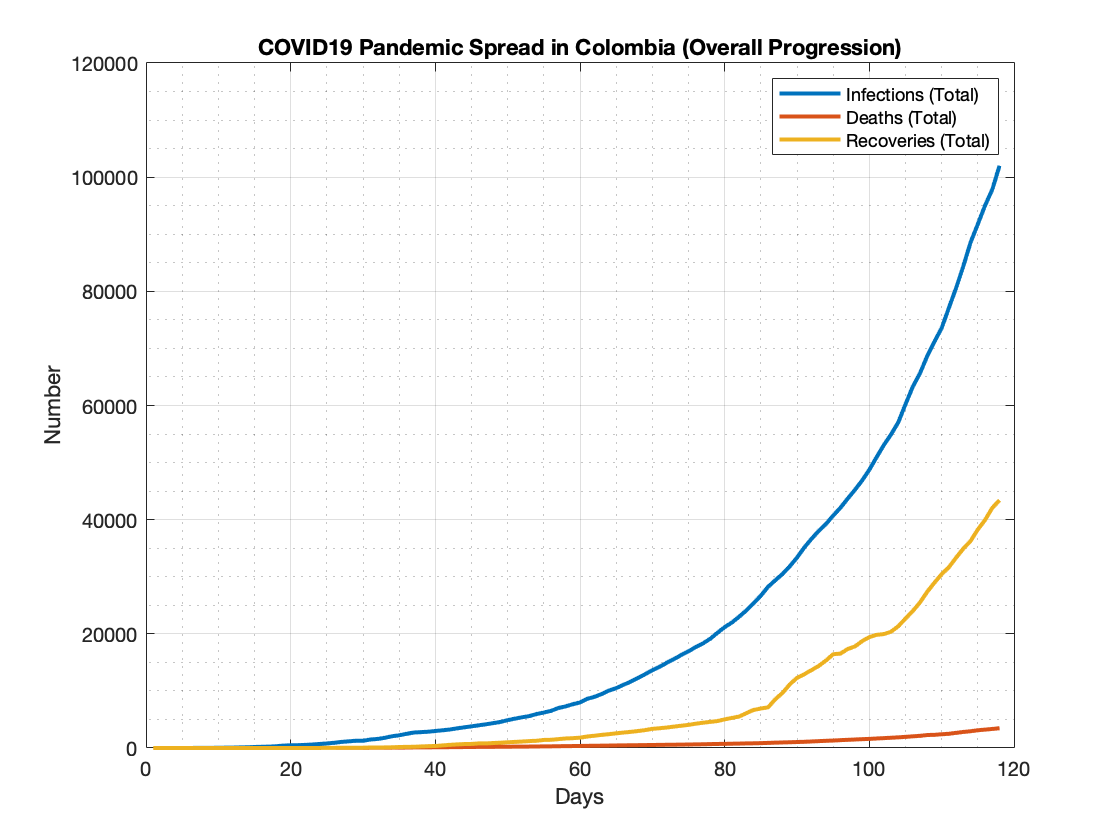

plot(timeElapsed,totalInfections,timeElapsed,totalDeaths,timeElapsed, totalRecoveries, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Overall Progression)')
legend('Infections (Total)','Deaths (Total)','Recoveries (Total)')
grid on, grid minor

#### Fitting Curve to a Fifth Order Gaussian Model

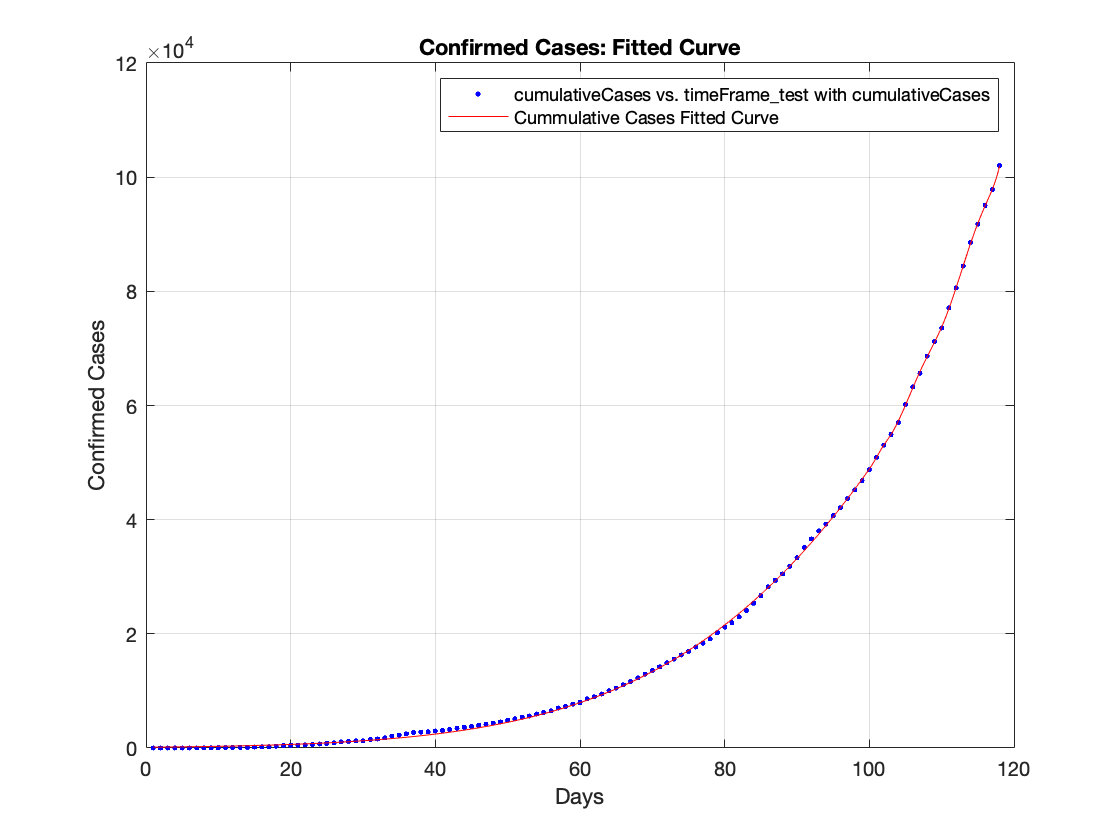

fittedCurve_cases = createFit(timeElapsed, data.TOTAL_CASOS);
xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases: Fitted Curve')

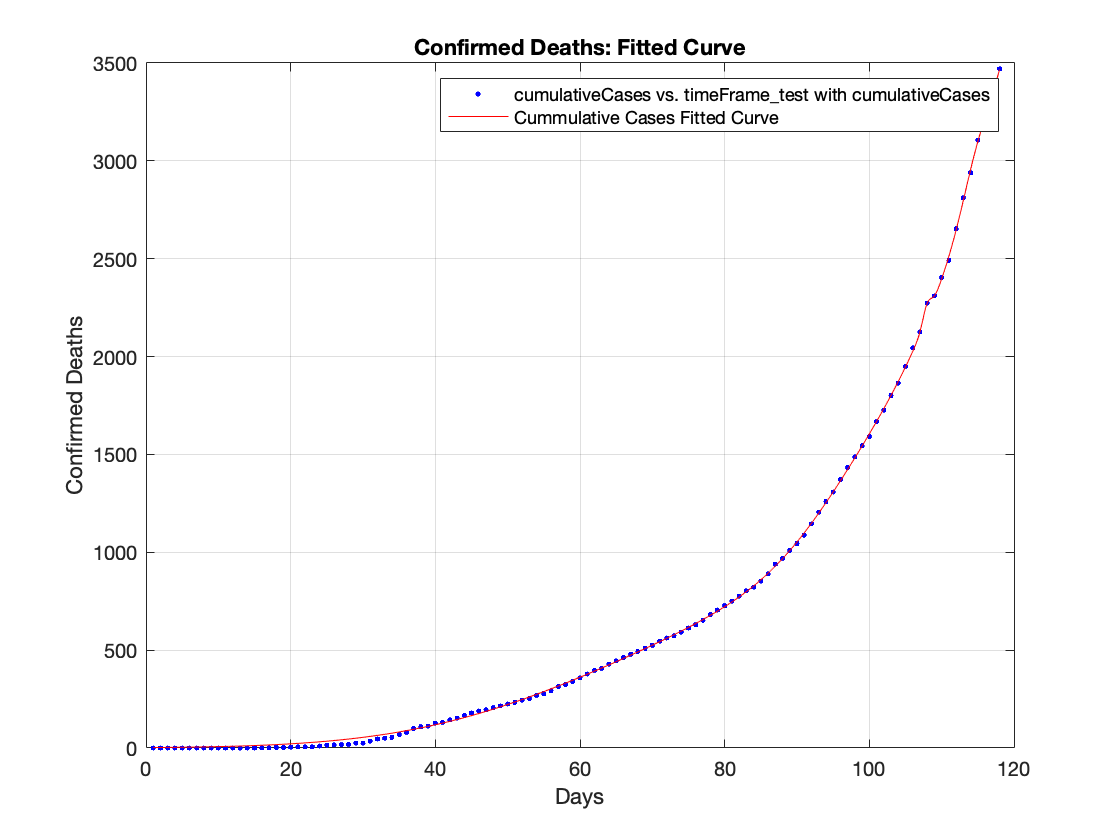

fittedCurve_deaths = createFit(timeElapsed, data.TOTAL_MUERTES);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths: Fitted Curve')

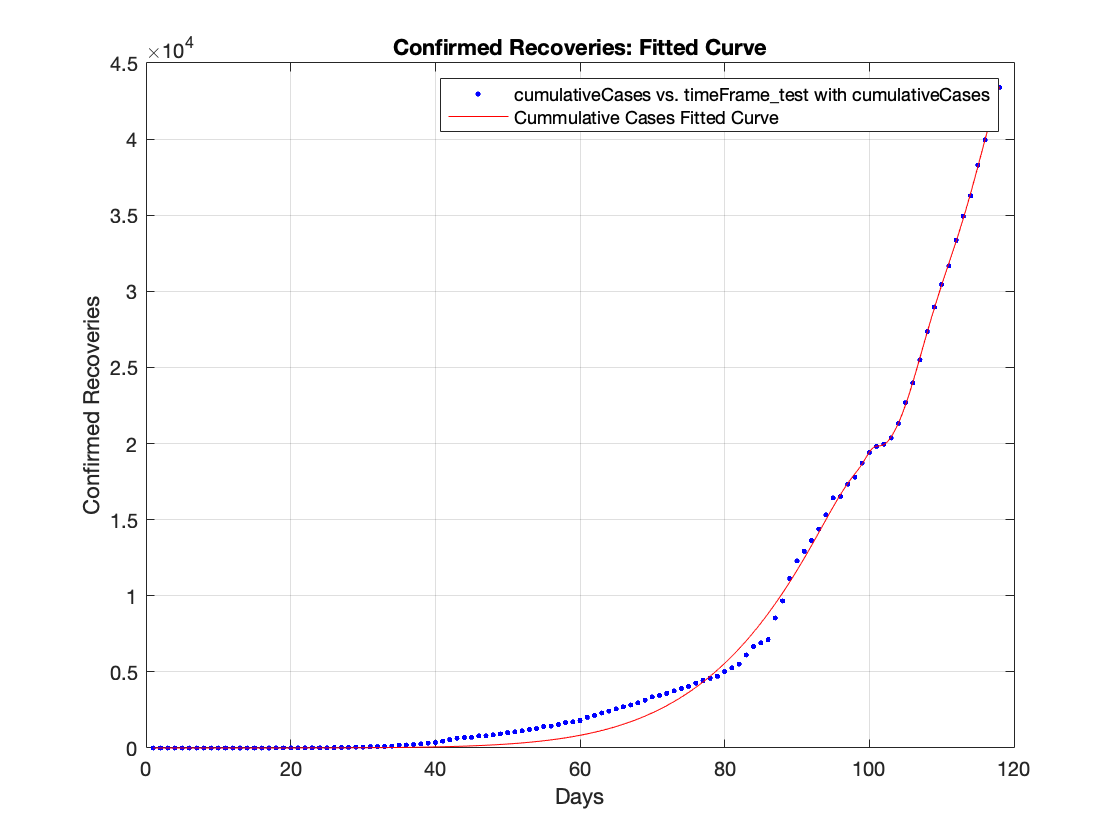

fittedCurve_recoveries = createFit(timeElapsed, data.TOTAL_RECUPERADOS);
xlabel('Days'), ylabel('Confirmed Recoveries'), title('Confirmed Recoveries: Fitted Curve')

## Predicting Cure Stage

totalPopulation = 48.9e6;                                       % Total Population (2018)
vaccineEffectiveness = 0.7;                                     % Number between 0.1 and 1
vaccineCost = 5;                                                % Vaccine cost in USD.
conversionRate = 3758.05;                                       % 1 USD to COP conversion ratio.
availableBudget = 10e9 / conversionRate                         % Available budget (in USD)

availableBudget = 2.6610e+06

availableDoses = floor(availableBudget/vaccineCost)             % Available Doses (Vaccine)

availableDoses = 532190